%Purpose:
    %Econ 525-Spring2019
%Note:
    %This m-file is dependent upon TreasuryYields.xlsx.
    %TFind interpretations for 1b and 1e in Malik_Jabati_HW6_Interpretations.docx.
%Author:
    %Malik Jabati — 01Mar2019
    %UNC Honor Pledge: I certify that no unauthorized assistance has been received or given in the completion of this work.
%Assumptions:
    %Maturities: 1 Mo, 3 Mo, 6 Mo, 1 Yr, 2 Yr, 3 Yr, 5 Yr, 7 Yr, 10 Yr, 20 Yr, and 30 Yr
    %Database: Treasury.gov
    %Estimation Period: 1990 to 2016
    %Evaluation Period: 2017


## Load in data

%HouseKeeping
    clear all; close all; clc
    
    [num, txt, raw] = xlsread('TreasuryYields.xlsx','EstimationData');
    
    %Convert text values to number values
    DailyEstimationData = cellfun(@str2double, raw(2:end,2:end));
    
    DailyDates = x2mdate(num);  %convert from excel to matlab numbering

%Manually cleaned data. Diebold-Li model disregards NaN, so I left those untouched.
    
%Extract data for the last day of each month (estimation period)
    MonthYearMat = repmat((1990:2016)',1,12)';
    EOMDates = lbusdate(MonthYearMat(:),repmat((1:12)',27,1));
    MonthlyIndex = find(ismember(DailyDates,EOMDates));
    EstimationData = DailyEstimationData(MonthlyIndex,:);
    
%Extract data for the last day of each month (testing period)
    MonthYearMat_test = repmat((2017)',1,12)';
    EOMDates_test = lbusdate(MonthYearMat_test(:),repmat((1:12)',1,1));
    MonthlyIndex_test = find(ismember(DailyDates,EOMDates_test));
    TestData = DailyEstimationData(MonthlyIndex_test,:);
    

## 1. Fit a Diebold-Li yield curve model to the monthly U.S. Treasury curve from 1990 through 2016. Use the same maturities specified above.

% Explicitly set the time factor lambda
    lambda_t = .0609;
    
% Construct a matrix of the factor loadings
% Tenors associated with data
    TimeToMat = [1 3 6 12 24 36 60 84 120 240 360]';
    X = [ones(size(TimeToMat)) (1 - exp(-lambda_t*TimeToMat))./(lambda_t*TimeToMat) ...
        ((1 - exp(-lambda_t*TimeToMat))./(lambda_t*TimeToMat) - exp(-lambda_t*TimeToMat))];
    
% Preallocate the Betas
    Beta = zeros(size(EstimationData,1),3);

% Loop through and fit each end of month yield curve
    for jdx = 1:size(EstimationData,1)
        tmpCurveModel = DieboldLi.fitBetasFromYields(EOMDates(jdx),lambda_t*12,daysadd(EOMDates(jdx),30*TimeToMat),EstimationData(jdx,:)');
        Beta(jdx,:) = [tmpCurveModel.Beta1 tmpCurveModel.Beta2 tmpCurveModel.Beta3];
    end

## 1a. Use the same maturities specified above and create a plot of the factor loadings.

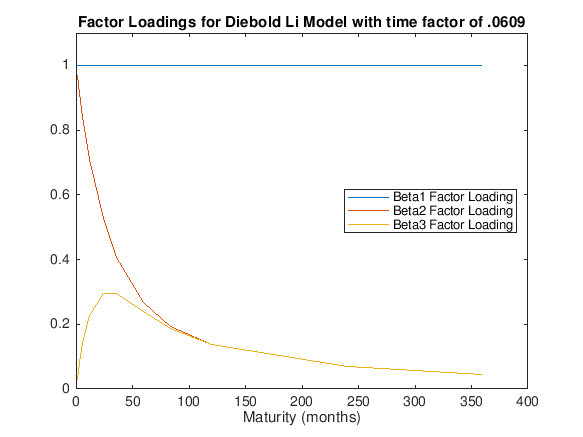

    
% Plot the factor loadings
    plot(TimeToMat,X)
    title('Factor Loadings for Diebold Li Model with time factor of .0609')
    xlabel('Maturity (months)')
    ylim([0 1.1])
    legend({'Beta1 Factor Loading','Beta2 Factor Loading','Beta3 Factor Loading'},'location','east')

## 1.b Interpret the plot of the factor loadings from part a (1-2 paragraphs).

%TODO

%See 1b in Malik_Jabati_HW6_Interpretations.docx

## 1.c Forecast the beta parameters with AR(1) specifications for all of 2017 (i.e. from 1mth ahead to 12mths ahead).


%Use method from Diebold-Li Matlab example

    ForecastBeta = zeros([12 3]); %preallocate array
    
    for i=1:12 %forecast betas for the next 12 months
        MonthsLag = i;
        
        %Beta1
        tmpBeta = regress(Beta(MonthsLag+1:end,1),[ones(size(Beta(MonthsLag+1:end,1))) Beta(1:end-MonthsLag,1)]);
        ForecastBeta(i,1) = [1 Beta(end,1)]*tmpBeta;
        
        %Beta2
        tmpBeta  = regress(Beta(MonthsLag+1:end,2),[ones(size(Beta(MonthsLag+1:end,2))) Beta(1:end-MonthsLag,2)]);
        ForecastBeta(i,2) = [1 Beta(end,2)]*tmpBeta;
        
        %Beta3
        tmpBeta  = regress(Beta(MonthsLag+1:end,3),[ones(size(Beta(MonthsLag+1:end,3))) Beta(1:end-MonthsLag,3)]);
        ForecastBeta(i,3) = [1 Beta(end,3)]*tmpBeta;
    end
    
    ForecastBeta

ForecastBeta =     3.1712   -2.7146   -1.9225
    3.1895   -2.7171   -1.9507
    3.1932   -2.7185   -1.9791
    3.1998   -2.7173   -2.0137
    3.2050   -2.7162   -2.0376
    3.2046   -2.7156   -2.0550
    3.2041   -2.7142   -2.0700
    3.2086   -2.7113   -2.0834
    3.2120   -2.7077   -2.1019
    3.2162   -2.7040   -2.1216


## 1.d  Compute the percent forecast error PFE as (forecast-actual)/actual. Construct a table with each month of 2017 as rows headings, each maturity examined as column headings, and table entries are PFE. See table below.

    ForecastYield = zeros([12 11]); %preallocate array
    
    %For each month ahead, multiply the factor loadings for each maturity (X) by the corresponding Beta factors [ForecastBeta(i,:)]. 
    %For each maturity, sum the three terms and place into ForecastYield array at the row for the corresponding month.
    
    for i=1:12 %forecast yields for the next 12 months
        ForecastYield(i,:) = sum((X .* repelem(ForecastBeta(i,:),11,1)),2)';
    end
        
    PFE_array = (ForecastYield - TestData)./TestData;
    
    TestMonths = {'Jan2017', 'Feb2017', 'March2017', 'April2017', 'May2017', 'June2017,'...
        'July2017', 'Aug2017', 'Sept2017', 'Oct2017', 'Nov2017', 'Dec2017'};
    
    Maturities = {'One_Month', 'Three_Month', 'Six_Month', 'One_Year', 'Two_Year', 'Three_Year',...
        'Five_Year', 'Seven_Year', 'Ten_Year', 'Twenty_Year', 'Thirty_Year'};
    
    PFE = array2table(PFE_array,'RowNames',TestMonths,'VariableNames',Maturities)

PFE = 12×11 table
                 One_Month    Three_Month    Six_Month    One_Year      Two_Year     Three_Year    Five_Year    Seven_Year    Ten_Year    Twenty_Year    Thirty_Year
                 _________    ___________    _________    _________    __________    __________    _________    __________    ________    ___________    ___________

    Jan2017      -0.037284     0.027857      -0.029815    -0.039227    -0.0084535      0.032117     0.044607      0.018615    0.036068     0.026588       -0.029617 
    Feb2017        0.24108      0.03441      -0.082486    -0.071416     -0.025

## 1.e Interpret your findings from part c (1-2 paragraphs).

%TODO

%See 1e in Malik_Jabati_HW6_Interpretations.docx